# Settling Tube Rapid Grain Size Analysis

To use this application, set the variables in the **SETUP** section and press 'Run' in the 'Live Editor' panel to begin the data collection. If you'd prefer to use a traditional MATLAB script, you can use `SettlingTubeInterface.m` instead.

## CLEANUP

This clears the workspace and the command window.

clear; clc;

## SETUP

This is the only section which needs to be adjusted for each run. Note that the variable `settlingTubeLength` is constant. Unless this is the first time the code is run using a new settling tube, this variable doesn't need to be changed.

sampleName = 'ottawa_20-30_test';
drySedimentMass = 9.36; % g
minutes = 1; % number of minutes to collect data (usually 10 minutes for natural samples)
waterTemperature = 24; % degrees C
settlingTubeLength = 203.3; % cm

## **WARNING**: Changing the code below can break the application

## PACKAGE DATA AS STRUCTS

This makes it easy to send important variables to the functions we call in the next steps.

SampleVars = struct('minutes',minutes, ...
    'dry_weight_input',drySedimentMass);
STvars = struct('waterTemperature',waterTemperature, ...
    'st_length',settlingTubeLength);

## TAKE MEASUREMENTS WITH THE MASS BALANCE

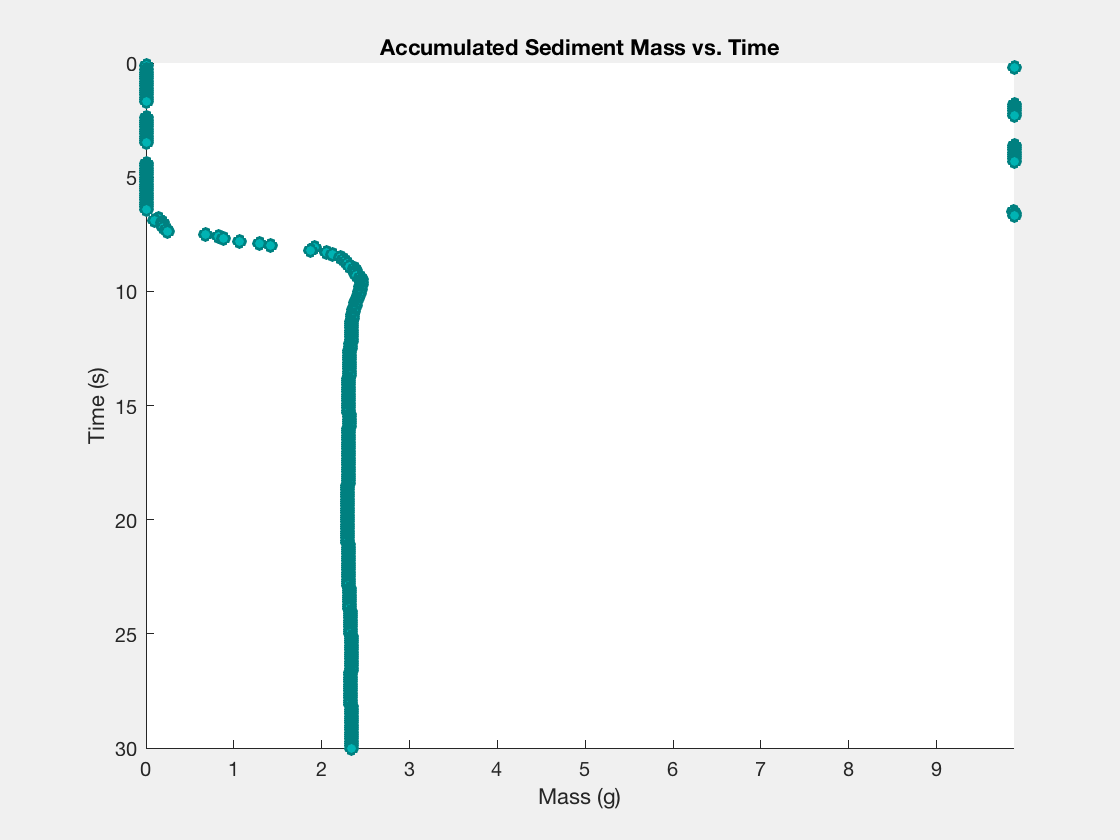

results = runSettlingTube(SampleVars, STvars);

## RUN THE STATISTICS

grainStatistics(drySedimentMass, results.grainSizeResults)

Weight Error is >5%

Total Immersed Weight (grams): 		5.67

Cumulative Total Weight (grams):	2.29

Percent Weight Error: 			-59.63



folkWardStats(results.grainSizeResults, phiPercentiles(results.grainSizeResults))

PHI 5%	= -0.98
PHI 16%	= -0.95
PHI 25%	= -0.91
PHI 50%	= -0.83
PHI 75%	= -0.73
PHI 84%	= -0.64
PHI 95%	= -0.53

MODE = -0.75 PHI		72.93 Cumulative Weight %

Following are the Folk-Ward Statistical Parameters:

Graphic Mean: 				-0.8048		: GRANULES
Including Graphic Standard Deviation: 	0.1444		: WELL SORTED
Including Graphic Skewness: 		0.2749		: NEAR SYMMETRICAL
Graphic Kurtosis: 			0.9998		: MESOKURTIC
Normalized Kurtosis: 			0.4999



methodOfMoments(results.grainSizeResults)

MEAN X =		-0.6561
VARIANCE =		0.0605
SKEWNESS =		5.3547
STD DEVIATION =		0.2460
KURTOSIS =		35.9448



## PLOT RESULTS

results.massPlot = plotMass(results.massPlot, results.dataMassTimeseries);

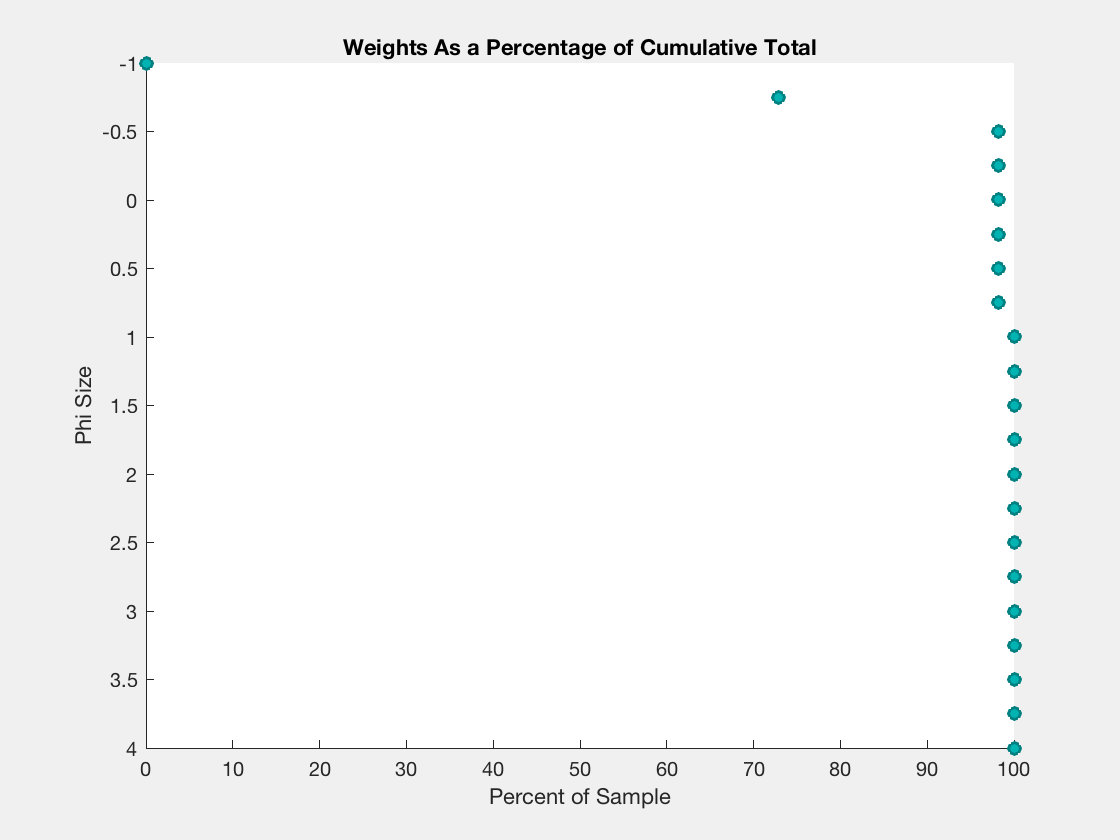

cumulativeCurvePlot = plotCumulativeCurve(results.grainSizeResults);

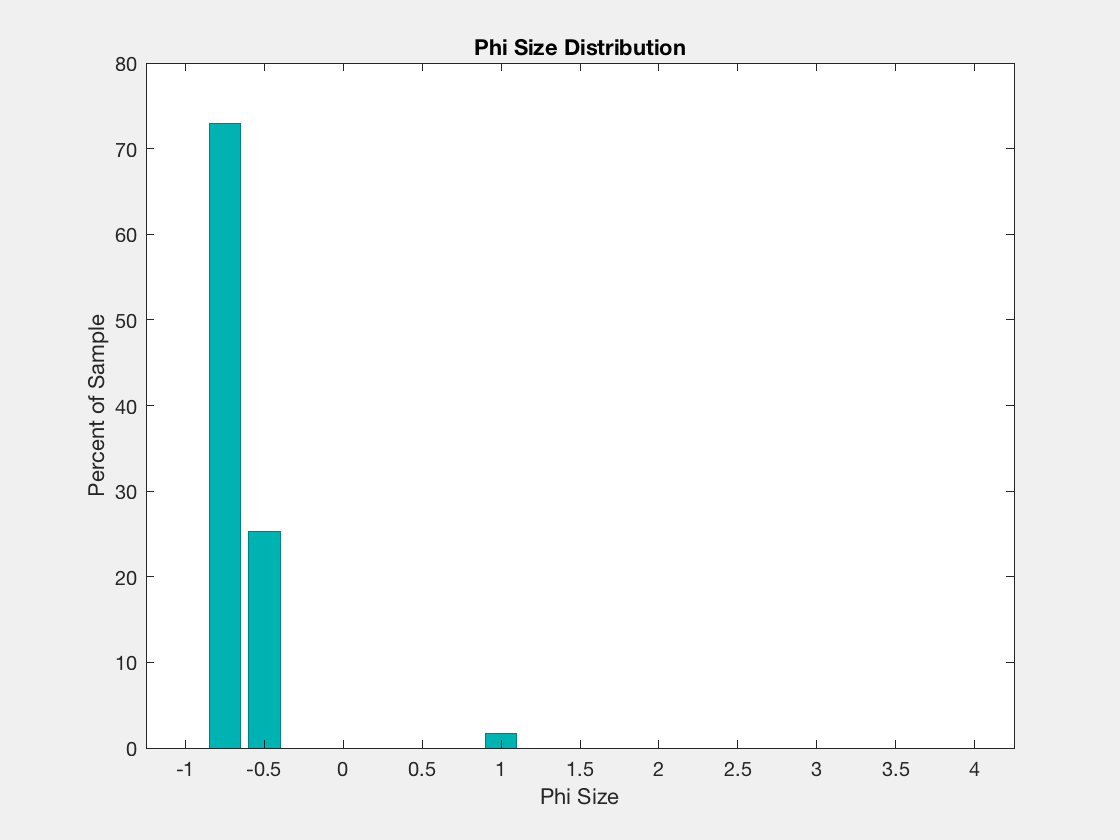

phiSizeDistribution = plotPhiDistribution(results.grainSizeResults);

## SAVE RESULTS

NOTE: This happens automatically if you are in the SedSettle directory

sampleLongName = strcat(sampleName,'_', ...
    string(datetime('now','Format','d-MMM-y_HH:mm')));
pwdParts = strsplit(pwd,'/');
if strcmp(pwdParts(end), 'SedSettle') == 1
    workspaceOut = fullfile('results',sampleLongName);
else % if not in the SedSettle directory, prompt to choose a save location
    msgbox('Select a directory to save the SedSettle results in.')
    selpath = uigetdir(pwd,'Select save location for SedSettle results');
    workspaceOut = fullfile(selpath,sampleLongName);
end
warning('off','MATLAB:Figure:FigureSavedToMATFile')
save(strcat(workspaceOut,'.mat'))

disp('Settling tube data collection COMPLETE')

Settling tube data collection COMPLETE
